3)

caul es la diferencia entre las funciones?

**ikine: **solucion numerica a la cinemateca inversa, sirve para 6 grados de libertad o mas pero si se requiere para menos se puede dar una opcion que dice que parametros no es nesesario tener en cuenta

**ikine6: **solucion analitica para robots de 6 grados de libertad, estos deben estar con parametros dh estandar. 

**ikine3:** igual que ikine6 pero para robots que no tengan muñeca

**ikine_sym:** solucion inversa simbolica, da multiples posibles soluciones pero es una funcion experimental

**ikinem: **solucion numerica de por minimizacion, es una funcion en prototipo y esta aun en desarrollo

**ikunc: **sulucion numerica ignorando los limites de las articulaciones

¿Cual debe usarse para su robot y porque?

ikinem, ya que tenemos el robot on parametros dh modificados, tenemos restricciones en las articulaciones y las otras funciones no aun para su uso.

close all
L1=380;
L2=820;
L3=880;

L(1) = Link('revolute','alpha',      0,  'a', 0,'d',L1,'offset',    0, 'qlim',[-pi pi],'modified');
L(2) = Link('revolute','alpha',  -pi/2,  'a', 0,'d', 0,'offset',-pi/2, 'qlim',[-pi pi],'modified');
L(3) = Link('revolute','alpha',      0,  'a',L2,'d', 0,'offset',    0, 'qlim',[-67/180*pi 247*pi/180],'modified');
L(4) = Link('revolute','alpha',  -pi/2,  'a', 0,'d',L3,'offset',    0, 'qlim',[-210*pi/180 210*pi/180],'modified');
L(5) = Link('revolute','alpha',   pi/2,  'a', 0,'d', 0,'offset',    0, 'qlim',[-pi pi],'modified');
L(6) = Link('revolute','alpha',  -pi/2,  'a', 0,'d', 0,'offset',    0, 'qlim',[-210*pi/180 210*pi/180],'modified');
bot1=SerialLink(L,'name','Yaskawa HC20XP');

mth_tool = rt2tr(eye(3),[0 0 0])

mth_tool =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


bot1.tool = mth_tool

 
bot1 = 
 
Yaskawa HC20XP:: 6 axis, RRRRRR, modDH, slowRNE                  
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        380|          0|          0|          0|
|  2|         q2|          0|          0|    -1.5708|    -1.5708|
|  3|         q3|          0|        820|          0|          0|
|  4|         q4|        880|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|    -1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


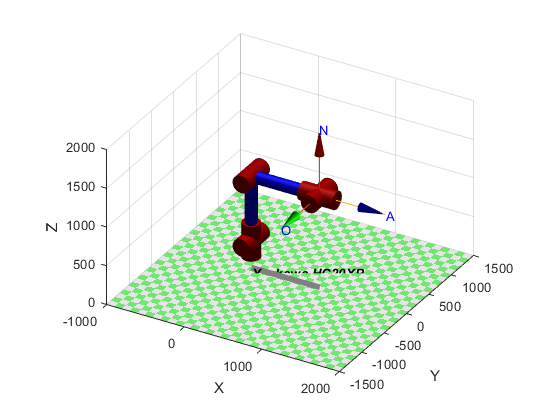

bot1.plot([0 0 0 0 0 0],'workspace',[-1000 2000 -1500 1500 0 2000],'noa', 'view',[30 30])

Comparacion

q(1,:)=[0 0 0 0 0 0];
q(2,:)=[0 0 0 pi/2 pi -pi/3];
q(3,:)=[-pi/3 -pi/2 pi/2 0 0 0];
q(4,:)=[pi/4 0 pi -pi/3 pi/2 pi/4];
qsize=size(q);
for i=1:qsize(1)
    T(i)=bot1.fkine(q(i,:));
    tabdata(i,:)=[T(i).t' rad2deg(tr2rpy(T(i)))];
end
array2table(rad2deg(q))

ans = 4×6 table
    Var1    Var2    Var3    Var4    Var5    Var6
    ____    ____    ____    ____    ____    ____

      0       0       0       0       0       0 
      0       0       0      90     180     -60 
    -60     -90      90       0       0       0 
     45       0     180     -60      90      45 


array2table(tabdata,'VariableNames',{'x', 'y', 'z', 'roll', 'pich', 'yaw'})

ans = 4×6 table
       x           y          z       roll       pich       yaw  
    _______    __________    ____    _______    ______    _______

        880    3.6739e-15    1200          0       -90       -180
        880    3.6739e-15    1200        -90       -60         90
         30       -51.962     380          0       -90        120
    -622.25       -622.25    1200    -50.768    37.761    -108.43


Calculada a mano

for i=1:qsize(1)
    qm(i,:)=invkine(T(i));
end
array2table(rad2deg(qm))

ans = 4×6 table
       Var1        Var2       Var3      Var4         Var5        Var6
    __________    _______    ______    _______    ___________    ____

    2.3921e-16      35.34    111.46    -30.361    -3.7064e-15    135 
    2.3921e-16      35.34    111.46     83.819     1.0892e-14    135 
           -60    0.82491    150.54     60.308         1.9144    135 
          -135     -8.769    76.696     11.788         30.986    -45 


Peter Corck

for i=1:qsize(1)
    qpt(i,:)=bot1.ikine(T(i));
end
array2table(rad2deg(qpt))

ans = 4×6 table
    Var1     Var2         Var3         Var4         Var5         Var6  
    ____    _______    ___________    _______    ___________    _______

      0           0              0          0              0          0
      0           0              0          0              0          0
    -60         -90             90     170.04    -2.3777e-09    -170.04
     45     -94.043    -6.0158e-15    -87.669         60.082     130.33


function q = invkine(T)
    
    alpha0=0;       a0=0;   d1=380;     
    alpha1=-pi/2;   a1=0;   d2=0;       
    alpha2=0;       a2=820; d3=0;       
    alpha3=-pi/2;   a3=0;   d4=880;   
    alpha4=pi/2;    a4=0;   d5=0;   
    alpha5=-pi/2;   a5=0;   d6=0;   
    
    p = T.t;
    n = T.n;
    o = T.o;
    a = T.a;
    xp=p(1); yp=p(2); zp=p(3);
    nx=n(1); ny=n(2); nz=n(3);
    ox=o(1); oy=o(2); oz=o(3);
    ax=a(3); ay=a(2); az=a(3); 
    L=0; % la distancia en la direcion aproach de el unto pa la muñeca
    %punto de la muñeca
    l1=d1;
    l2= a2;
    l3=d4;
    xw=xp-L*ax;
    yw=yp-L*ay;
    zw=yp-L*az;
    p2w=[xw yw zw-l1];
    %solucion q1
    q1=atan2(yw,xw);
    r=sqrt(yw^2+xw^2);
    %solucion q3
    c3=((p2w(3)^2) +(r^2) -(l2^2) -(l3^2) )/(2*l2*l3);
    s3=sqrt(1-c3^2);
    q3=atan2(s3,c3);
    %solucion q2
    alpha= atan2(l3*sin(q3),l2+l3*cos(q3));
    beta = atan2 (p2w(3),r);
    q2_arriba=beta+alpha;
    q2_abajo=beta-alpha;
    
%     MTH_10 =                             rt2tr(rotz(q1)   ,[0 0 380]');
%     MTH_21 = rt2tr(rotx(-pi/2),[0 0 0]')*rt2tr(rotz(q2_arriba-pi/2),[0 0 0]');
%     MTH_32 = rt2tr(eye(3)   ,[820 0 0]')*rt2tr(rotz(q3)     ,[0 0 0]');
%     MTH_30 = MTH_10*MTH_21*MTH_32;
    theta1=q1;
    theta2=q2_arriba-pi/2;
    theta3=q3;
    %% cinematica directa 1-3
    T0_1=MTH(alpha0,a0,d1,theta1);
    T1_2=MTH(alpha1,a1,d2,theta2);
    T2_3=MTH(alpha2,a2,d3,theta3);
    T0_3=T0_1*T1_2*T2_3;
    
    R3_0=T0_3(1:3,1:3);
    Rdeseada=[nx ox ax; ny oy ay; nz oz az];
    R3_6=R3_0*Rdeseada;
    q4_1=atan2(-R3_6(1,3),R3_6(2,3));
    q4_2=atan2(-R3_6(1,3),-R3_6(2,3));
    q5=atan2(-R3_6(3,3),sqrt(1-(R3_6(3,3))^2));
    q6_1=atan2( -R3_6(3,1),R3_6(3,1));
    q6_2=atan2(-R3_6(3,2),-R3_6(3,2));
    
    q=[q1 q2_arriba q3 q4_1 q5 q6_1];
end

function [T_dh]=MTH( a_i,alpha_i,d,theta)
    % esta funcion toma los parametros dh modificada y  da como resultado
    % se le p asan los angulos en grados
    %alpha_(i-1) a_(i-1) di theta i
    %syms alpha_i a_i d theta
    T1=trotx (alpha_i);
    T2=transl(a_i,0,0);
    T3=trotz(theta);
    T4=transl(0,0,d);
    T_dh=T1*T2*T3*T4;
end